disp(table_nrOfexamples)

    uWovels    nrOfexamples
    _______    ____________

     {'a'}          12     
     {'e'}          12     
     {'i'}          12     
     {'o'}          12     
     {'u'}          12     
     {'y'}          12     



Każdych głosek jest po 12

Podział na trening i test

disp(table_nrOfexamples3)

    uWovels    nrOfexamplesTraining    nrOfexamplesTest
    _______    ____________________    ________________

     {'a'}              8                     4        
     {'e'}              8                     4        
     {'i'}              8                     4        
     {'o'}              8                     4        
     {'u'}              8                     4        
     {'y'}              8                     4        



Sekcja cvpartition

disp(table_nrOfexamples4_a)

    uWovels    nrOfexamplesTraining2    nrOfexamplesTest2
    _______    _____________________    _________________

     {'a'}               8                      4        
     {'e'}               8                      4        
     {'i'}               8                      4        
     {'o'}               9                      3        
     {'u'}               9                      3        
     {'y'}               9                      3        



disp(table_nrOfexamples4_b)

    uWovels    nrOfexamplesTraining2    nrOfexamplesTest2
    _______    _____________________    _________________

     {'a'}               9                      3        
     {'e'}               9                      3        
     {'i'}               8                      4        
     {'o'}               8                      4        
     {'u'}               9                      3        
     {'y'}               8                      4        



disp(table_nrOfexamples4_c)

    uWovels    nrOfexamplesTraining2    nrOfexamplesTest2
    _______    _____________________    _________________

     {'a'}               9                      3        
     {'e'}               9                      3        
     {'i'}               9                      3        
     {'o'}               8                      4        
     {'u'}               8                      4        
     {'y'}               8                      4        



Classification Learner

Cross Validation - dane są dzielone na k częsci, jedna część jest wykorzystywana jako dane treningowe, a reszta do walidacji. Proces powtarzamy k razy, aby każdy fragment miał szansę być treningowym i metryki uśredniamy

Najlepszy model:

Val Accuracy: 70.8%

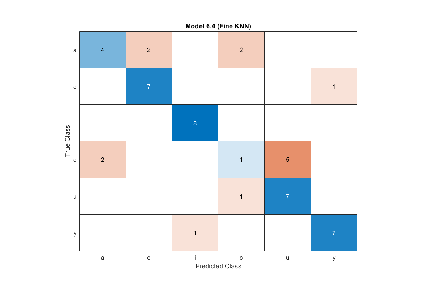

I = imread('model1_1.png');
figure, imshow(I);

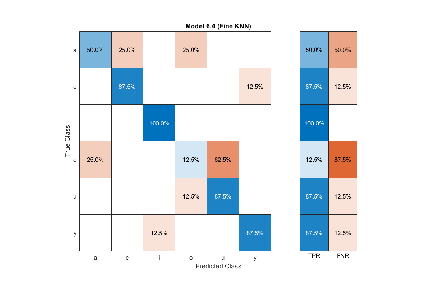

I = imread('model1_2.png');
figure, imshow(I);

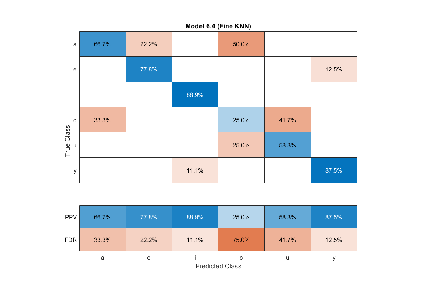

I = imread('model1_3.png');
figure, imshow(I);

Drugi najlepszy model: 58,3%

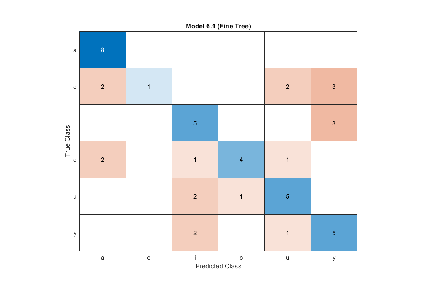

I = imread('model2_1.png');
figure, imshow(I);

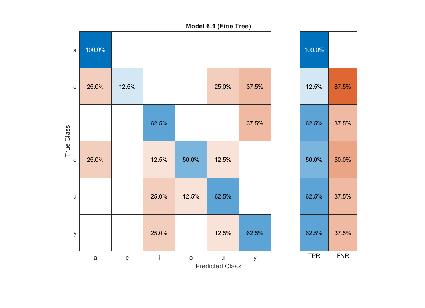

I = imread('model2_2.png');
figure, imshow(I);

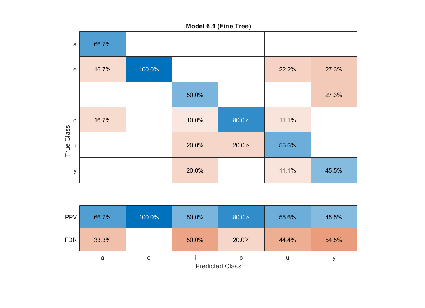

I = imread('model2_3.png');
figure, imshow(I);

Najlepszy model najczęściej myli (o, u) 

True positive rate: stosunek true positive do (true positive + false negative)

False negative rate: stosunek false negative do (false negative + true positive)

PCA

Najlepszy model val_acc: 81,2%

Wartości validationAccuracy oraz accuracyTrain różnią się ponieważ jedna z metryk jest generowana za pomocą walidacji krzyżowej podczas uczenia, a druga otrzymana na całym zbiorze danych przez przygotowany model

Dokładność oraz confusion matrix na zbiorze testowym

% macierz pomylek
CTst = confusionmat(formantsTableTest.vowel,testResults)

CTst =      4     0     0     0     0     0
     0     4     0     0     0     0
     0     0     3     0     1     0
     0     0     0     2     2     0
     0     0     0     0     3     1
     0     1     0     0     0     3



% dokładność klasyfikatora
accuracy1 = mean(cellfun(@eq,testResults, formantsTableTest.vowel))

accuracy1 = 0.7917

Dlaczego stosujemy 3 zbiory

- testowy wykorzystujemy do nauczenia modelu

- walidacyjny daje nam informacje czy model dobrze uogólnia już podczas nauki

- testowy jest nam potrzebny jako ostateczne wyznaczenie jakości modelu po procesie nauczania

Experiment Manager:

Najlepszy model

val_acc: 77,08%

numNeighbors: 1, distance: minkowski, standarize: false

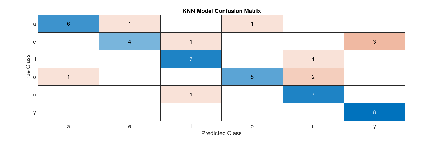

I = imread('experiment_conf.png');
figure, imshow(I);

Wykorzystanie cech MFCC

1. MFCC - mel-frequency cepstrum coefficients - rodzaje cech dźwiękowych otrzymywanych sygnałów mowy, każdy reprezentuje pewien filter

2. więcej obserwacji dla jednego pliku audio jest spowodowane przetwarzaniem sygnału za pomocą okna przesuwnego

normalizacja jest konieczna, ponieważ cechy MFCC i pitch mają różną skalę i zakres

## Podsumowanie

#### Rezultaty - wyżej

#### Analiza i wnioski

- Liczebność dla każdej klasy powinna być podobna, żeby model mógł w równym stopniu nauczyć się każdej. W przeciwnym wypadku będzie lepiej się sprawował dla niektórych danych, albo faworyzował odpowiedzi.

- Liczebności grup nie są takie same, ponieważ klasyfikator po częsci losowo wybiera rozmiar zbioru uczącego i testowego

- hold-out - podział danych na treningowe i walidacyjne w proporcji np 80/20, cross-validation - podział zbioru na k grup, każda po kolei jest traktowana jako zbiór walidacyjny, a reszta elementów jako zbiór treningowy, dla małych zbiorów lepsza bedzię cross-validation.

- odpowiedź w rezultatach

- odpowiedź w rezultatach

- PCA redukuje rozmiar przestrzeni danych, dzięki czemu model ma lepiej podane informacje, jest mniej szumu. Ułatwia też wizualizację danych. Wszystko to ułatwia/poprawia trenowanie modelu

- w rezultatach

- w rezultatach

- w rezultatach

#### Pytania

- rozpoznawanie mowy (speech to text), rozpoznawanie osoby na podsawie mowy, rozpoznawanie emocji

- Wykorzystanie preprocesingu PCA może znacznie poprawić wyniki, narzędzie takie jak Experiment z ćwiczenia czy GridSearch ułatwiają i przyśpieszają znalezienie odpowiednich parametrów dla modelu

- Na czym polega zasada działania algorytmu wykorzystującego MFCC i pitch